% Feel free to add code anywhere you find necessary to solve the task.
% as a guide, we have provide recommendation where to add code

## DO NOT CHANGE ANYTHING HERE - Setting up the remote api

vrep=remApi('remoteApi'); % using the prototype file (remoteApiProto.m)

Note: always make sure you use the corresponding remoteApi library
(i.e. 32bit Matlab will not work with 64bit remoteApi, and vice-versa)


vrep.simxFinish(-1); % just in case, close all opened connections
clientID=vrep.simxStart('127.0.0.1',19999,true,true,5000,5);

% connection status
connected = false;

% motor handles
leftMotor = 0;
rightMotor = 0;

% sensor reading buffers
detectionState = zeros(1, 6);   % Detection status
detectedPoint = zeros(6, 3);    % Point (vector)
range = zeros(1, 6);                % Euclidean distance
% driving velocity
driveVel = 0;

if (clientID>-1)
    
    connected = true;
    disp('Connected to remote API server');
    
    % get object handles
    [~,leftMotor]=vrep.simxGetObjectHandle(clientID,'Pioneer_p3dx_leftMotor',vrep.simx_opmode_blocking);
    [~,rightMotor]=vrep.simxGetObjectHandle(clientID,'Pioneer_p3dx_rightMotor',vrep.simx_opmode_blocking);
    [~,leader]=vrep.simxGetObjectHandle(clientID,'Pioneer_leader',vrep.simx_opmode_blocking);
    [~,follower]=vrep.simxGetObjectHandle(clientID,'Pioneer_follower',vrep.simx_opmode_blocking);
    % get camera system handles
    [~,rgbdCam]=vrep.simxGetObjectHandle(clientID,'rgbd_sensor',vrep.simx_opmode_blocking);
    
    % initialize camera
    [~, resolution, rgb_image]=vrep.simxGetVisionSensorImage2(clientID,rgbdCam,1,vrep.simx_opmode_streaming);
    [~, d_resolution, depth_image]=vrep.simxGetVisionSensorDepthBuffer2(clientID,rgbdCam,vrep.simx_opmode_streaming);
end

Connected to remote API server


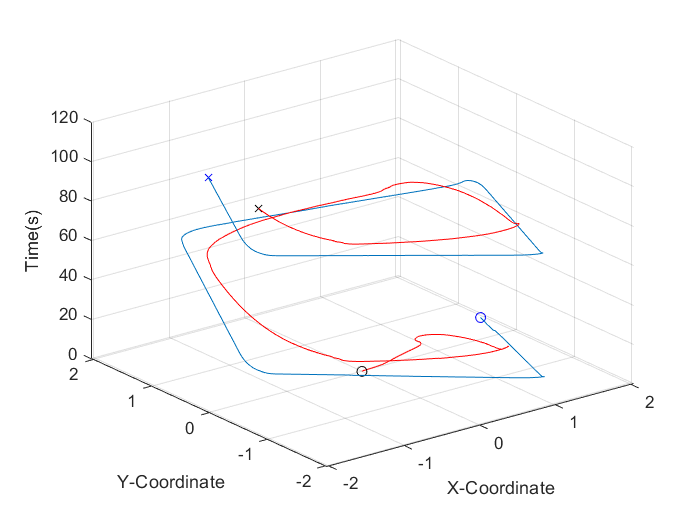

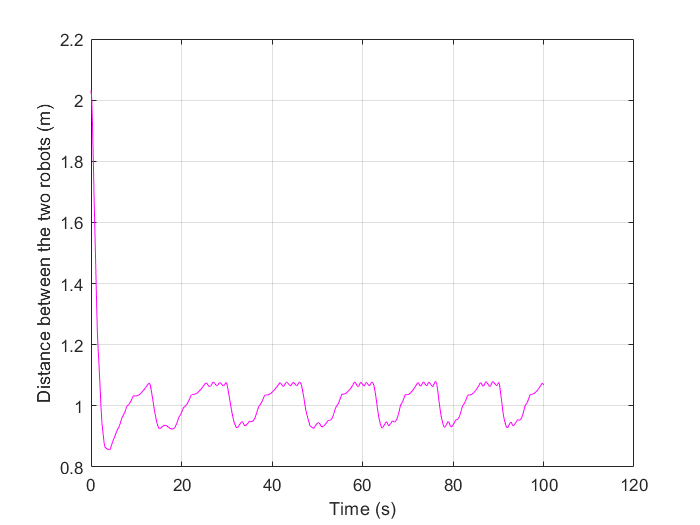


if (connected)
    clc;
    clf;
    last_error_x=0;
    integral_x=0;
    last_error_sum=0;
    k=1;j=1;t=0;
    while true
        % get image
        [~, resolution, rgb_image]=vrep.simxGetVisionSensorImage2(clientID,rgbdCam,1,vrep.simx_opmode_streaming);
        [~, d_resolution, depth_image]=vrep.simxGetVisionSensorDepthBuffer2(clientID,rgbdCam,vrep.simx_opmode_streaming);
        [~, d_resolution, depth_image]=vrep.simxGetVisionSensorDepthBuffer2(clientID,rgbdCam,vrep.simx_opmode_buffer );
        [~, resolution, rgb_image]=vrep.simxGetVisionSensorImage2(clientID,rgbdCam,1,vrep.simx_opmode_buffer );
%         pause(0.1);
        integral_sum=0;
        %        imshow(rgb_image); % uncomment to see rgb image
        %        imshow(depth_image); % uncomment to see depth image
        % make sure there is a valid image
        if(size(rgb_image, 1) > 0)
            % heading control using rgb_image matrix
            % distance control using depth_image matrix
            target_x=32;  %(32,32) is central elemant of (64X64) matrix
            current_x=0;  % initialising blob position
            current_sum=0;
            row_range=19;
            target_sum=840;
            %calculating current blob position
            for col=[1:64]
                if sum(rgb_image(:,col))>0
                    current_x=col;
                    break
                end
            end
            % calculating target sum from depth matrix elememts
            % using it only once to get targeted values
            if size(depth_image)~=[64,64]
                current_sum= target_sum;
            else
                for l=[1:64]
                    current_sum = current_sum + sum(depth_image(l,:));
                    if mean(depth_image(l,:))<1
%                         target_sum=current_sum
                        break
                    end
                end
            end
            % calculating sum of elements till first row to target row
            %                 for i=[1:64]
            %                   current_sum = current_sum + sum(depth_image(i,:));
            %                 end
            % heading control using Pid controller
            kp=1.1;kd=0.00;ki=0.005;
            error_x = (target_x-current_x)/64; %normalising error value
            integral_x=integral_x+error_x;
            %depth control using Pid control
            
            kp_sum=0.7;kd_sum=0.07;ki_sum=0.032;
            error_sum= (target_sum-current_sum)/100; %normalising error value
            integral_sum=integral_sum+error_sum;
            if current_x==0  %no error condition
                [~]=vrep.simxSetJointTargetVelocity(clientID, leftMotor, 0, vrep.simx_opmode_blocking);
                [~]=vrep.simxSetJointTargetVelocity(clientID, rightMotor, 0, vrep.simx_opmode_blocking);
            else
                if j==1
                    clock1=tic;
                    t=toc(clock1);
                end
                dt=t-toc(clock1);
                t=toc(clock1);
                v_x=kp*(error_x)+kd*(error_x-last_error_x)/dt+ki*integral_x*dt;
                v_sum=kp_sum*(error_sum)+kd_sum*(error_sum-last_error_sum)/dt+ki_sum*integral_sum*dt;
                [returnCode, pos_leader]=vrep.simxGetObjectPosition(clientID,leader,-1,vrep.simx_opmode_blocking);
                [returnCode, pos_follower]=vrep.simxGetObjectPosition(clientID,follower,-1,vrep.simx_opmode_blocking);
                dist= sqrt((pos_leader(1)-pos_follower(1))^2+(pos_leader(2)-pos_follower(2))^2);
                dist_t(k,:)=[dist,t];
                pos_t_leader(k,:)=[pos_leader(1),pos_leader(2),t];
                pos_t_follower(k,:)=[pos_follower(1),pos_follower(2),t];
                [~]=vrep.simxSetJointTargetVelocity(clientID, leftMotor, -v_x-v_sum, vrep.simx_opmode_blocking);
                [~]=vrep.simxSetJointTargetVelocity(clientID, rightMotor, v_x-v_sum, vrep.simx_opmode_blocking);
                k=k+1;
                j=j+1;
            end
            last_error_x=error_x;
            last_error_sum=error_sum;
            
        end
        if t>100
            break
        end
    end
    
    % stop wheels
    [~]=vrep.simxSetJointTargetVelocity(clientID, leftMotor, 0, vrep.simx_opmode_blocking);
    [~]=vrep.simxSetJointTargetVelocity(clientID, rightMotor, 0, vrep.simx_opmode_blocking);
    
    f1=figure('name','Positions of the two robots wrt Time');
    plot3(pos_t_leader(:,1),pos_t_leader(:,2),pos_t_leader(:,3));
    hold on;
    grid on;
    plot3(pos_t_leader(1,1),pos_t_leader(1,2),pos_t_leader(1,3),'ob');
    plot3(pos_t_leader(end,1),pos_t_leader(end,2),pos_t_leader(end,3),'xb')
    plot3(pos_t_follower(:,1),pos_t_follower(:,2),pos_t_follower(:,3),'r');
    plot3(pos_t_follower(1,1),pos_t_follower(1,2),pos_t_follower(1,3),'ok');
    plot3(pos_t_follower(end,1),pos_t_follower(end,2),pos_t_follower(end,3),'xk');
    zlabel("Time(s)")
    xlabel("X-Coordinate");
    ylabel("Y-Coordinate");
    hold off;
    
    f2=figure("Name","Distance between the robots wrt Time");
    plot(dist_t(:,2),dist_t(:,1),'Color','m');
    hold on;grid on;
    xlabel("Time (s)");
    ylabel("Distance between the two robots (m)");
    
    
    % Now close the connection to V-REP:
    vrep.simxFinish(clientID);
else
    disp('Failed connecting to remote API server');
end

vrep.delete(); % call the destructor!